clc; clear all;
robot_name = 'kukaIiwa7';
robot = loadrobot(robot_name, 'DataFormat', 'column');

Loading **KukaIiwa7** Robot

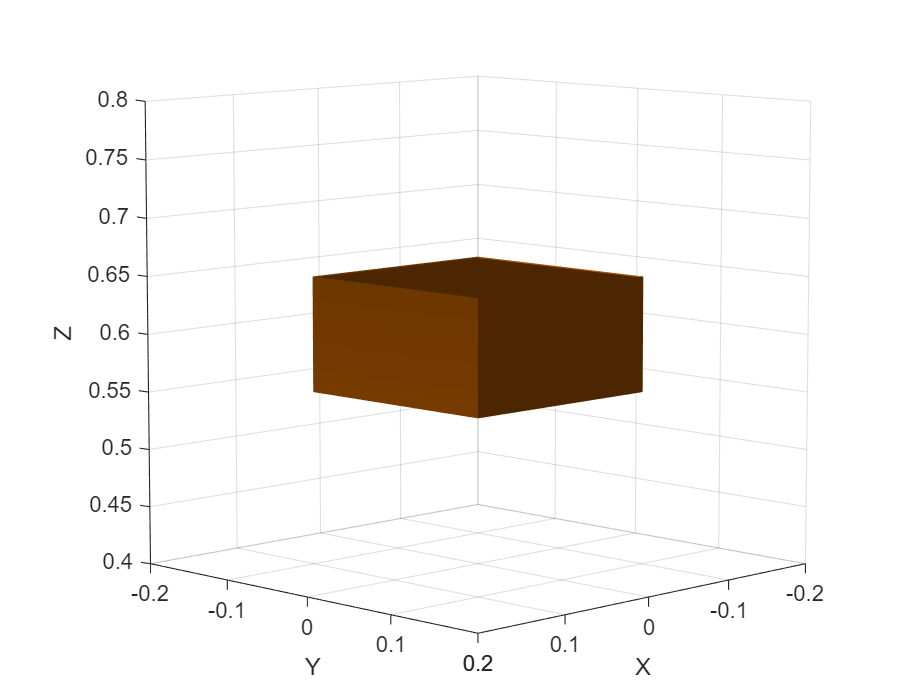

numJoints = numel(homeConfiguration(robot));
endEffector = 'iiwa_link_ee_kuka';
helperCreateObstaclesKINOVA;


%taskInit = trvec2tform([[0.4 0 0.2]])*axang2tform([0 1 0 pi]);
%taskInit = trvec2tform([[0.3 0.0 0.5]])*axang2tform([0 1 0 pi]); % Scene 2

R_horizontal = [1  0  0;    % x-axis: to the right
                0  0  1;    % y-axis: upward (for constraint)
                0 -1  0];   % z-axis: forward horizontally

taskInit = trvec2tform([0.3 0.0 0.5]) * rotm2tform(R_horizontal);
ik = inverseKinematics('RigidBodyTree', robot);
ik.SolverParameters.AllowRandomRestart = false;
weights = [1 1 1 1 1 1];

currentRobotJConfig = findCollisionFreeIK(robot, world, endEffector, taskInit);

  
%taskFinal = trvec2tform([0.25 0.0 0.05])*axang2tform([0 1 0 pi]);   % Scene 2
taskFinal = trvec2tform([0.25 0.0 0.05]) * rotm2tform(R_horizontal);  % Scene 2
anglesFinal = rotm2eul(taskFinal(1:3,1:3),'XYZ');
poseFinal = [taskFinal(1:3,4);anglesFinal'];

finalRobotJConfig   = findCollisionFreeIK(robot, world, endEffector, taskFinal);

assert(~checkCollision(robot,currentRobotJConfig,world,"IgnoreSelfCollision","on"))
assert(~checkCollision(robot,finalRobotJConfig,   world,"IgnoreSelfCollision","on"))

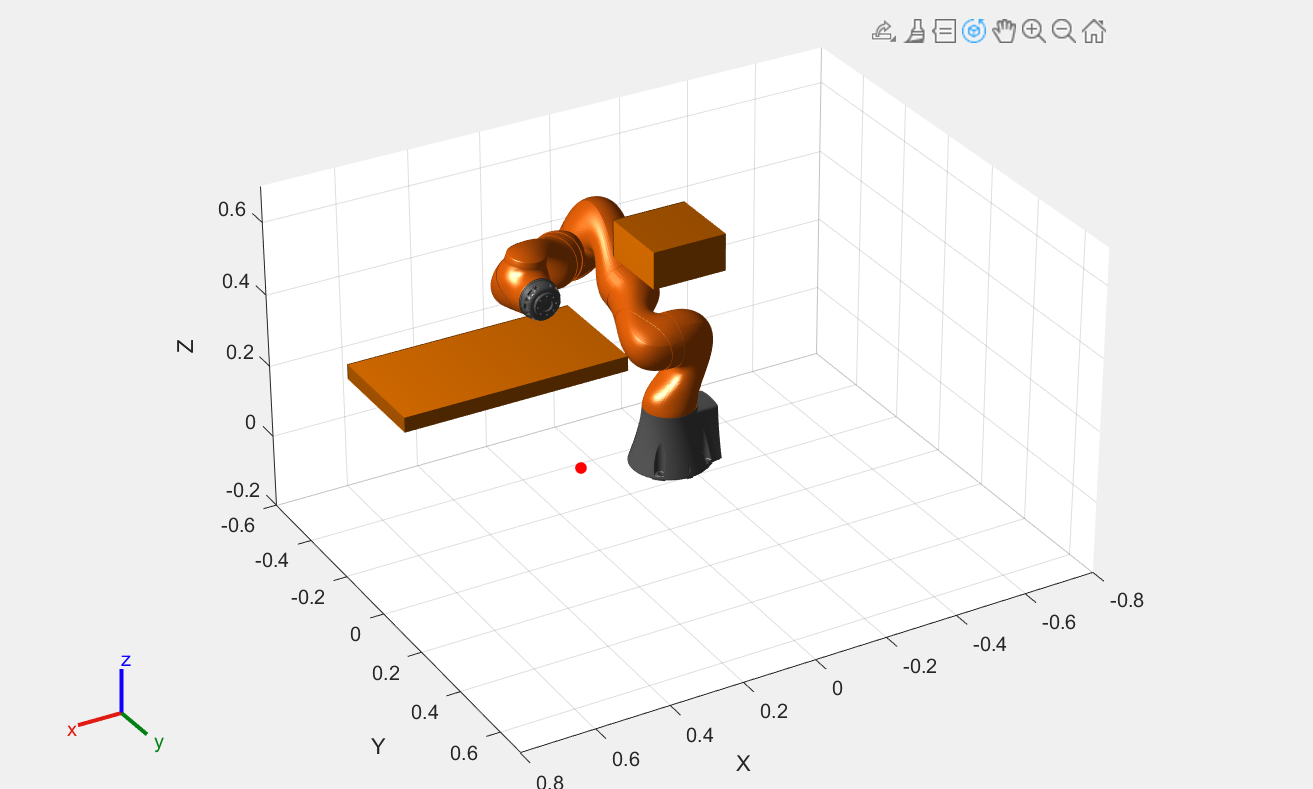

x0 = [currentRobotJConfig', zeros(1,numJoints)];
helperInitialVisualizerKINOVA;

safetyDistance = 0.01; 

Elapsed time is 1.010366 seconds.


Qtheta = 6.2056e+03

RAR = 18.9422

Previous Qθ = 6463.531399 | New Qθ = 6205.584239 | ΔQ = 257.947160
Elapsed time is 0.940670 seconds.


Qtheta = 5.9514e+03

RAR = 18.9418

Previous Qθ = 6205.584239 | New Qθ = 5951.411166 | ΔQ = 254.173073
Elapsed time is 0.913340 seconds.


Qtheta = 5.7620e+03

RAR = 18.9419

Previous Qθ = 5951.411166 | New Qθ = 5761.976021 | ΔQ = 189.435145
Elapsed time is 0.905204 seconds.


Qtheta = 5.6115e+03

RAR = 18.9418

Previous Qθ = 5761.976021 | New Qθ = 5611.498862 | ΔQ = 150.477160
Elapsed time is 0.931224 seconds.


Qtheta = 5.3964e+03

RAR = 18.9414

Previous Qθ = 5611.498862 | New Qθ = 5396.413517 | ΔQ = 215.085345
Elapsed time is 0.953533 seconds.


Qtheta = 5.2292e+03

RAR = 18.9413

Previous Qθ = 5396.413517 | New Qθ = 5229.236848 | ΔQ = 167.176669
Elapsed time is 1.076186 seconds.


Qtheta = 5.0166e+03

RAR = 18.9413

Previous Qθ = 5229.236848 | New Qθ = 5016.593804 | ΔQ = 212.643044
Elapsed time is 0.991489 seconds.


Qtheta = 4.8877e+03

RAR = 18.9411

Previous Qθ = 5016.593804 | New Qθ = 4887.665573 | ΔQ = 128.928231
Elapsed time is 1.029644 seconds.


Qtheta = 4.7823e+03

RAR = 18.9410

Previous Qθ = 4887.665573 | New Qθ = 4782.277225 | ΔQ = 105.388349
Elapsed time is 1.046158 seconds.


Qtheta = 4.6628e+03

RAR = 18.9411

Previous Qθ = 4782.277225 | New Qθ = 4662.797715 | ΔQ = 119.479510
Elapsed time is 0.965019 seconds.


Qtheta = 4.4736e+03

RAR = 18.9407

Previous Qθ = 4662.797715 | New Qθ = 4473.637696 | ΔQ = 189.160019
Elapsed time is 0.966913 seconds.


Qtheta = 4.3727e+03

RAR = 18.9407

Previous Qθ = 4473.637696 | New Qθ = 4372.691750 | ΔQ = 100.945946
Elapsed time is 1.082312 seconds.


Qtheta = 4.3219e+03

RAR = 18.9409

Previous Qθ = 4372.691750 | New Qθ = 4321.875064 | ΔQ = 50.816686
Elapsed time is 0.997880 seconds.


Qtheta = 4.1693e+03

RAR = 18.9407

Previous Qθ = 4321.875064 | New Qθ = 4169.318651 | ΔQ = 152.556413
Elapsed time is 0.953086 seconds.


Qtheta = 4.0832e+03

RAR = 18.9408

Previous Qθ = 4169.318651 | New Qθ = 4083.226022 | ΔQ = 86.092630
Elapsed time is 0.987791 seconds.


Qtheta = 4.0192e+03

RAR = 18.9412

Previous Qθ = 4083.226022 | New Qθ = 4019.152002 | ΔQ = 64.074019
Elapsed time is 1.021290 seconds.


Qtheta = 3.9326e+03

RAR = 18.9414

Previous Qθ = 4019.152002 | New Qθ = 3932.641280 | ΔQ = 86.510723
Elapsed time is 0.947921 seconds.


Qtheta = 3.8465e+03

RAR = 18.9417

Previous Qθ = 3932.641280 | New Qθ = 3846.500007 | ΔQ = 86.141273
Elapsed time is 0.976220 seconds.


Qtheta = 3.7185e+03

RAR = 18.9419

Previous Qθ = 3846.500007 | New Qθ = 3718.508595 | ΔQ = 127.991411
Elapsed time is 0.953916 seconds.


Qtheta = 3.6633e+03

RAR = 18.9423

Previous Qθ = 3718.508595 | New Qθ = 3663.276788 | ΔQ = 55.231808
Elapsed time is 0.944520 seconds.


Qtheta = 3.5838e+03

RAR = 18.9424

Previous Qθ = 3663.276788 | New Qθ = 3583.768126 | ΔQ = 79.508662
Elapsed time is 1.053640 seconds.


Qtheta = 3.5149e+03

RAR = 18.9424

Previous Qθ = 3583.768126 | New Qθ = 3514.876370 | ΔQ = 68.891756
Elapsed time is 1.236473 seconds.


Qtheta = 3.4400e+03

RAR = 18.9426

Previous Qθ = 3514.876370 | New Qθ = 3440.024586 | ΔQ = 74.851785
Elapsed time is 0.992317 seconds.


Qtheta = 3.3662e+03

RAR = 18.9430

Previous Qθ = 3440.024586 | New Qθ = 3366.151128 | ΔQ = 73.873457
Elapsed time is 0.964350 seconds.


Qtheta = 3.2986e+03

RAR = 18.9428

Previous Qθ = 3366.151128 | New Qθ = 3298.552497 | ΔQ = 67.598631
Elapsed time is 0.954877 seconds.


Qtheta = 3.1638e+03

RAR = 18.9428

Previous Qθ = 3298.552497 | New Qθ = 3163.812448 | ΔQ = 134.740049
Elapsed time is 0.964367 seconds.


Qtheta = 3.1118e+03

RAR = 18.9427

Previous Qθ = 3163.812448 | New Qθ = 3111.834545 | ΔQ = 51.977903
Elapsed time is 0.953609 seconds.


Qtheta = 3.0405e+03

RAR = 18.9427

Previous Qθ = 3111.834545 | New Qθ = 3040.476048 | ΔQ = 71.358497
Elapsed time is 0.968580 seconds.


Qtheta = 3.0082e+03

RAR = 18.9426

Previous Qθ = 3040.476048 | New Qθ = 3008.179527 | ΔQ = 32.296521
Elapsed time is 0.976127 seconds.


Qtheta = 2.9638e+03

RAR = 18.9426

Previous Qθ = 3008.179527 | New Qθ = 2963.756015 | ΔQ = 44.423512
Elapsed time is 0.965014 seconds.


Qtheta = 2.9038e+03

RAR = 18.9429

Previous Qθ = 2963.756015 | New Qθ = 2903.808755 | ΔQ = 59.947260
Elapsed time is 0.981225 seconds.


Qtheta = 2.8022e+03

RAR = 18.9429

Previous Qθ = 2903.808755 | New Qθ = 2802.157230 | ΔQ = 101.651525
Elapsed time is 0.967763 seconds.


Qtheta = 2.7189e+03

RAR = 18.9429

Previous Qθ = 2802.157230 | New Qθ = 2718.878707 | ΔQ = 83.278524
Elapsed time is 0.966774 seconds.


Qtheta = 2.6395e+03

RAR = 18.9429

Previous Qθ = 2718.878707 | New Qθ = 2639.465754 | ΔQ = 79.412952
Elapsed time is 0.952343 seconds.


Qtheta = 2.5753e+03

RAR = 18.9428

Previous Qθ = 2639.465754 | New Qθ = 2575.316191 | ΔQ = 64.149564
Elapsed time is 0.989743 seconds.


Qtheta = 2.5245e+03

RAR = 18.9430

Previous Qθ = 2575.316191 | New Qθ = 2524.488026 | ΔQ = 50.828165
Elapsed time is 1.040496 seconds.


Qtheta = 2.4473e+03

RAR = 18.9431

Previous Qθ = 2524.488026 | New Qθ = 2447.265377 | ΔQ = 77.222649
Elapsed time is 1.030100 seconds.


Qtheta = 2.3950e+03

RAR = 18.9434

Previous Qθ = 2447.265377 | New Qθ = 2394.962883 | ΔQ = 52.302495
Elapsed time is 0.943141 seconds.


Qtheta = 2.3338e+03

RAR = 18.9434

Previous Qθ = 2394.962883 | New Qθ = 2333.812129 | ΔQ = 61.150754
Elapsed time is 0.939669 seconds.


Qtheta = 2.2650e+03

RAR = 18.9436

Previous Qθ = 2333.812129 | New Qθ = 2265.023814 | ΔQ = 68.788315
Elapsed time is 0.931614 seconds.


Qtheta = 2.2345e+03

RAR = 18.9434

Previous Qθ = 2265.023814 | New Qθ = 2234.455471 | ΔQ = 30.568343
Elapsed time is 0.937063 seconds.


Qtheta = 2.1520e+03

RAR = 18.9433

Previous Qθ = 2234.455471 | New Qθ = 2152.045595 | ΔQ = 82.409876
Elapsed time is 0.933332 seconds.


Qtheta = 2.0827e+03

RAR = 18.9432

Previous Qθ = 2152.045595 | New Qθ = 2082.713016 | ΔQ = 69.332579
Elapsed time is 0.948895 seconds.


Qtheta = 2.0433e+03

RAR = 18.9433

Previous Qθ = 2082.713016 | New Qθ = 2043.345581 | ΔQ = 39.367435
Elapsed time is 0.962720 seconds.


Qtheta = 1.9515e+03

RAR = 18.9434

Previous Qθ = 2043.345581 | New Qθ = 1951.510561 | ΔQ = 91.835020
Elapsed time is 0.955056 seconds.


Qtheta = 1.9076e+03

RAR = 18.9433

Previous Qθ = 1951.510561 | New Qθ = 1907.556474 | ΔQ = 43.954087
Elapsed time is 0.928306 seconds.


Qtheta = 1.8450e+03

RAR = 18.9430

Previous Qθ = 1907.556474 | New Qθ = 1844.968199 | ΔQ = 62.588274
Elapsed time is 0.937677 seconds.


Qtheta = 1.7848e+03

RAR = 18.9431

Previous Qθ = 1844.968199 | New Qθ = 1784.841737 | ΔQ = 60.126462
Elapsed time is 0.940178 seconds.


Qtheta = 1.7368e+03

RAR = 18.9436

Previous Qθ = 1784.841737 | New Qθ = 1736.812840 | ΔQ = 48.028897
Elapsed time is 0.947601 seconds.


Qtheta = 1.6887e+03

RAR = 18.9443

Previous Qθ = 1736.812840 | New Qθ = 1688.738450 | ΔQ = 48.074390
Elapsed time is 0.955666 seconds.


Qtheta = 1.6431e+03

RAR = 18.9446

Maximum iteration (50) has reached.
STOMP Finished.


isTrajectoryInCollision = logical
   0


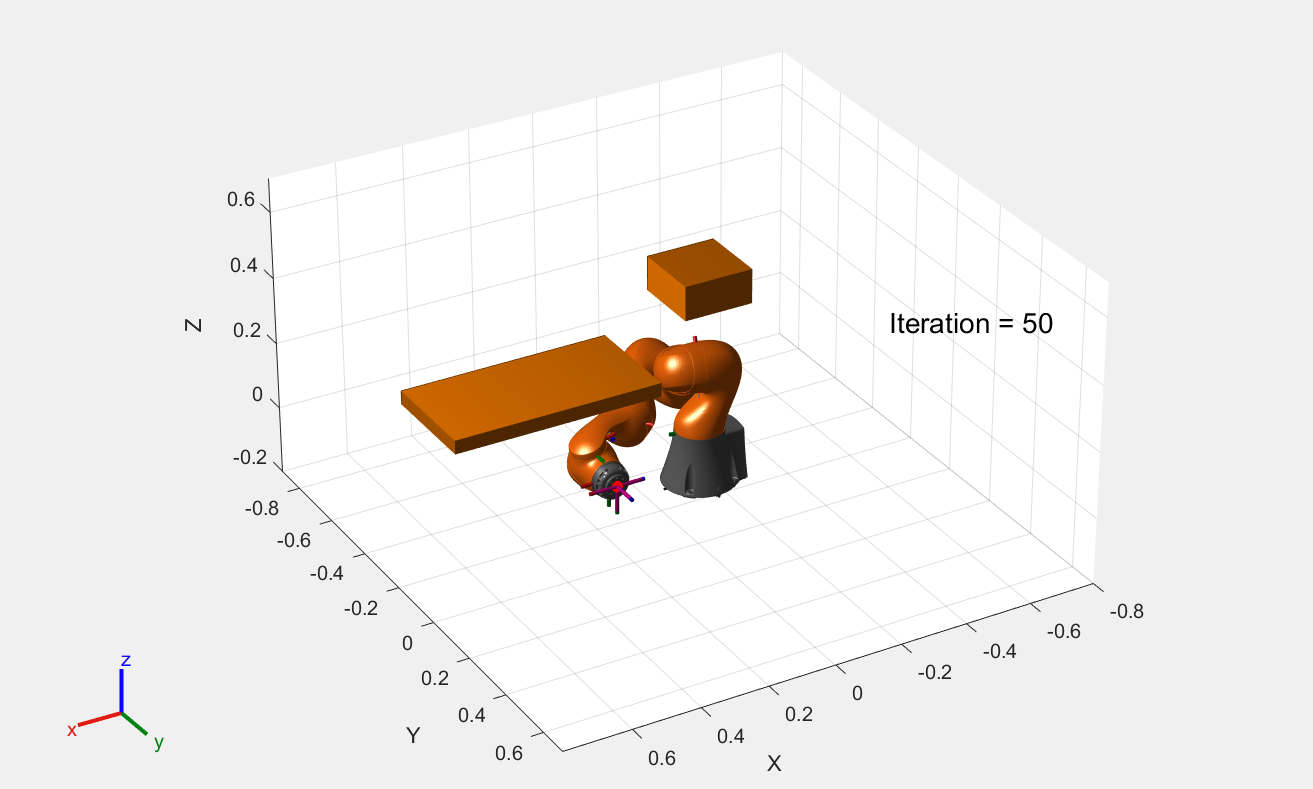

enableVideoTraining = 1;
enableVideo = 1;
helperSTOMP;